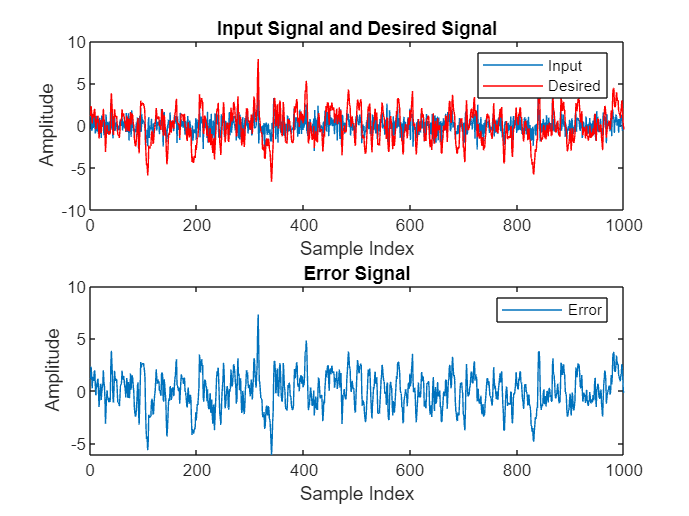

% RLS Algorithm for Active Noise Control
clear all; close all; clc;

% Parameters
mu = 0.99;      % Forgetting factor
M = 64;         % Filter order
L = 64;         % Block size

% Input signal (noise reference)
x = randn(1000,1);

% Desired signal (noise to be cancelled)
d = filter([1 0.5],[1 -0.7],x);

% Initialize weight vector and inverse correlation matrix
w = zeros(M,1);
P = eye(M)/0.001;

% Buffers
x_buf = zeros(M,1);
y_buf = zeros(length(d),1);

% Main loop
for n = (M+1):length(x)
    
    % Shift input buffer
    x_buf = [x(n:-1:n-M+1)]; % Fixed indexing
    
    % FIR filter output
    y = w'*x_buf;
    y_buf(n) = y;
    
    % Error signal
    e = d(n) - y;
    
    % Update inverse correlation matrix
    k = P*x_buf/(mu + x_buf'*P*x_buf);
    P = (P - k*x_buf'*P)/(mu + x_buf'*P*x_buf); % Fixed updating formula
    
    % Update weight vector
    w = w + k*e;
    
end

% Plot results
figure;
subplot(2,1,1);
plot(x); hold on; plot(d,'r'); legend('Input','Desired');
title('Input Signal and Desired Signal');
xlabel('Sample Index');
ylabel('Amplitude');
subplot(2,1,2);
plot(d-y_buf); legend('Error');
title('Error Signal');
xlabel('Sample Index');
ylabel('Amplitude');